clear;
trans_data_01 = zeros(4,3)

trans_data_01 =      0     0     0
     0     0     0
     0     0     0
     0     0     0


for x = 1:4
    filename = sprintf('charac_01_s%d.mat', x);
    data = load(filename);
    trans_data_01(x,:) = data.solution_trans(end-2:end)';
    disp(['Loaded file: ' filename]);
end

Loaded file: charac_01_s1.mat
Loaded file: charac_01_s2.mat
Loaded file: charac_01_s3.mat
Loaded file: charac_01_s4.mat


trans_data_02 = zeros(4,3)

trans_data_02 =      0     0     0
     0     0     0
     0     0     0
     0     0     0


Loaded file: charac_02_s1.mat
Loaded file: charac_02_s2.mat
Loaded file: charac_02_s3.mat
Loaded file: charac_02_s4.mat


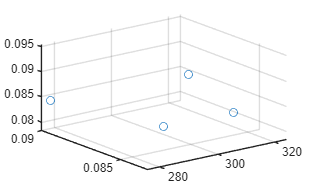

x=1;
for x = 1:4
    filename = sprintf('charac_02_s%d.mat', x);
    data = load(filename);
    trans_data_02(x,:) = data.solution_trans(end-2:end)';
    disp(['Loaded file: ' filename]);
end

mean(trans_data_02,1)

ans =   307.9198    0.0718    0.0847


mean(trans_data_01,1)

ans =   298.3827    0.0867    0.0845


CROR1=mean([trans_data_01;trans_data_02],1)';